%edit 用于创建文件
clc %清除命令窗口内容
clear %删除工作区中所储存的所有变量
a = pi %pi在matlab中为内置值

a =        3.1416


%变量名必须以字母开头，长度不限，但只有前63个字符有意义
%允许的字符只有字母、数字和下划线，区分大小写
array1 = [1, 2, 3] %定义一维数组

array1 =      1     2     3


array2 = [1 2 3] %逗号是可选项，可用逗号替代

array2 =      1     2     3


matrix1 = [1 2 3; 10 20 30; 100 200 300] %定义二维数组，分号为行分隔符

matrix1 =      1     2     3
    10    20    30
   100   200   300


matrix2 = [1 2 3; 10 20 30; 100 200 300]; %尾部添加分号可使命令不在窗口中重复出现
whos %查找已定义变量

  Name         Size            Bytes  Class     Attributes

  a            1x1                 8  double              
  array1       1x3                24  double              
  array2       1x3                24  double              
  matrix1      3x3                72  double              
  matrix2      3x3                72  double              



isvarname array1 %查看变量名是否合法

ans = logical
   1


iskeyword %列出保留关键字

ans = 20×1 cell 数组
    {'break'     }
    {'case'      }
    {'catch'     }
    {'classdef'  }
    {'continue'  }
    {'else'      }
    {'elseif'    }
    {'end'       }
    {'for'       }
    {'function'  }
    {'global'    }
    {'if'        }
    {'otherwise' }
    {'parfor'    }
    {'persistent'}
    {'return'    }
    {'spmd'      }
    {'switch'    }
    {'try'       }
    {'while'     }


sin = 4 %允许创建变量名与内联函数名称相同，但会造成sin函数功能缺失

sin =      4


clear sin %删除sin变量
which sin %检查sin此时为函数还是变量

built-in (D:\application\matlabR2025b\toolbox\matlab\elfun\sin)


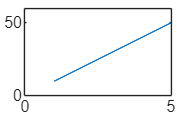

x = [1 2 3 4 5];
y = [10 20 30 40 50];
plot(x, y) %plot为画图命令，创建的图片会被新创建的图片覆盖

clc
clear
a = cos(1) %赋值运算

a =        0.5403


b = sin(1)

b =       0.84147


%标量运算
a + b %加法运算

ans =        1.3818


a - b %减法运算

ans =      -0.30117


a * b %乘法运算

ans =       0.45465


a / b %除法运算

ans =       0.64209


a ^ b %指数运算，exp()用于以e为底的指数运算

ans =       0.59569


%计算顺序：1.括号内运算，从内向外(小括号运算之前必须有乘除运算) 2.指数运算 3.乘除运算，从左到右 4.加减运算，从左到右
radius = 5;
height = 10;
surface_area = 2*pi*radius^2 + 2*pi*radius*height %计算圆柱体表面积

surface_area =        471.24


array1 = [1:5]; %数组显示列表定义，以1为增量输出等间隔数组
array2 = [1:2:5]; %接受三个参数。第一个参数为起点，第二个参数为增量值，第三个参数为终点
array3 = 1:2:5; %方括号可以省略
matrix1 = [1 2 3; 4 5 6]

matrix1 =      1     2     3
     4     5     6


matrix2 = [1 2 3
           4 5 6] %让数组每行单独占据一行，则分号可省略

matrix2 =      1     2     3
     4     5     6


array4 = linspace(1, 10, 3); %linspace()接受初始值，终点值和取值总数量，输出等间隔分布的数组
array5 = logspace(1, 3, 3); %logspace()接受k的初始值，终点值和取值总数量，输出对数间隔分布的数组，数组中元素为10的k次幂
array6 = [1:pi/10:pi]; %数组定义语句内部可以包含数学运算
array6 = array6 + 5; %数组与标量进行加减运算，但不适用于乘除法

a = [1 2 3 4 5 6]

a =      1     2     3     4     5     6


b = [9 8 7 6 5 4]

b =      9     8     7     6     5     4


a.* b %按元素乘法

ans =      9    16    21    24    25    24


%a * b会报错，这是矩阵乘法，a和b的形式不符合矩阵乘法
a * 4

ans =      4     8    12    16    20    24


a.*4 %对于数组和标量乘法，两种乘法都可以

ans =      4     8    12    16    20    24


a.^b %按元素指数运算

ans =            1         256        2187        4096        3125        1296


a./b %按元素除法运算，注意对于数组与标量的除法只能用./不能用/

ans =       0.11111         0.25      0.42857      0.66667            1          1.5


degrees = [10 15 70 90]

degrees =     10    15    70    90


radians = degrees*pi/180 %角度转弧度

radians =       0.17453       0.2618       1.2217       1.5708


degrees' %数组转置运算

ans =     10
    15
    70
    90


Deg_to_R = [degrees', radians']

Deg_to_R =            10      0.17453
           15       0.2618
           70       1.2217
           90       1.5708


Deg_to_R' %二维数组转置运算

ans =            10           15           70           90
      0.17453       0.2618       1.2217       1.5708


sci_number = 6.02e23 %科学计数法，小数与指数间不能有空格

sci_number =      6.02e+23


clear, clc
A = 51.1 %matlab中都使用双精度浮点型

A =          51.1


C = 51 %整数也以浮点型存放和运算

C =     51


format long %定义类型为long，显示小数点后15位十进制数字
A

A =   51.100000000000001


format bank %定义类型为bank，显示小数点后2位十进制数字,但只适用于实数不适用于复数
A

A =          51.10


format default
B = 3+5i

B = 3.0000 + 5.0000i

format bank
B %显示3.00

B =           3.00


format short %定义类型为short，显示小数点后4位十进制数字
B

B = 3.0000 + 5.0000i

x = 60200000000000

x = 6.0200e+13

format short e %科学指数法，显示小数点后4位显示表示
x

x =    6.0200e+13


format long e %科学指数法，显示小数点后15位显示表示
x

x =      6.020000000000000e+13


format short eng %科学指数法，显示小数点后4位显示表示，指数为3的倍数
x

x =     60.2000e+012


format long eng %科学指数法，显示小数点后15位显示表示，指数为3的倍数
x

x =     60.2000000000000e+012


format + %对于各元素，若符号为正显示+，若符号为负显示-，若值为0不显示任何符号
D = [1 2 0 -1 -2]

D = ++ --


format rat %以分数形式表示
E = 0:0.1:1

E =        0              1/10           1/5            3/10           2/5            1/2            3/5            7/10           4/5            9/10           1       


%当不确定那种表示方式更合适时可采用 format short g或format long g
save test_data1 %储存工作区内容，接收文件名，储存为二进制文件称为MAT文件
save Workspace %储存工作区内容
load test_data1 %加载文件内容
what %查找当前文件夹内含有哪些MATLAB程序、函数和MAT文件


当前文件夹 E:\控制工程matlab 中的 MATLAB Live Code

matlab_notebook  

当前文件夹 E:\控制工程matlab 中的 MAT-files

Workspace   test_data1  




%run可用于运行当前程序

clear, clc
format short g
x = 1:10

x =      1     2     3     4     5     6     7     8     9    10


result1 = sqrt(x) %函数接收参数可以为标量或数组

result1 =             1       1.4142       1.7321            2       2.2361       2.4495       2.6458       2.8284            3       3.1623


rem(10, 3) %rem用于求余运算，接收两个参数，前者为被除数，后者为除数

ans =      1


d = [1 2 3; 4 5 6]

d =      1     2     3
     4     5     6


size(d) %sizeof函数可用于输出数组形状，输出为一个数组

ans =      2     3


help tan %help函数用于给出函数文档

--- tan 的帮助 ---

 tan - 以弧度表示的参量的正切
    此 MATLAB 函数 返回 X 的每个元素的正切。tan 函数按元素处理数组。该函数同时接受实数和
    复数输入。 对于 X 的实数值，tan(X) 返回区间 [-∞, ∞] 内的实数值。 对于 X 的复数
    值，tan(X) 返回复数值。

    语法
      Y = tan(X)

    输入参数
      X - 输入角（以弧度为单位）
        标量 | 向量 | 矩阵 | 多维数组 | 表 | 时间表

    输出参数
      Y - 输入角的正切
        标量 | 向量 | 矩阵 | 多维数组 | 表 | 时间表

    示例
      绘制正切函数图
      复角向量的正切

    另请参阅 tand, tanh, atan, atan2, <a href="m

doc tan %help函数用于给出函数文档独立窗口
abs(x) %绝对值函数

ans =      1     2     3     4     5     6     7     8     9    10


n = 5

n =      5


nthroot(x, n) %求x的n次方根的实数解，该函数不返回复数根

ans =             1       1.1487       1.2457       1.3195       1.3797        1.431       1.4758       1.5157       1.5518       1.5849


sign(x) %符号函数

ans =      1     1     1     1     1     1     1     1     1     1


log(x) %以e为底对数函数

ans =             0      0.69315       1.0986       1.3863       1.6094       1.7918       1.9459       2.0794       2.1972       2.3026


log10(x) %以10为底对数函数

ans =             0      0.30103      0.47712      0.60206      0.69897      0.77815       0.8451      0.90309      0.95424            1


round(x) %将x舍入为最接近的整数

ans =      1     2     3     4     5     6     7     8     9    10


N = 4

N =      4


y = 0.01234:0.00561:1.88684

y =       0.01234      0.01795      0.02356      0.02917      0.03478      0.04039        0.046      0.05161      0.05722      0.06283      0.06844      0.07405      0.07966      0.08527      0.09088      0.09649       0.1021      0.10771      0.11332      0.11893      0.12454      0.13015      0.13576      0.14137      0.14698      0.15259       0.1582      0.16381      0.16942      0.17503      0.18064      0.18625      0.19186      0.19747      0.20308      0.20869       0.2143      0.21991      0.22552      0.23113      0.23674      0.24235      0.24796      0.25357      0.25918      0.26479       0.2704      0.27601      0.28162      0.28723


round(y, N) %将x舍入为指定的小数位数

ans =        0.0123        0.018       0.0236       0.0292       0.0348       0.0404        0.046       0.0516       0.0572       0.0628       0.0684       0.0741       0.0797       0.0853       0.0909       0.0965       0.1021       0.1077       0.1133       0.1189       0.1245       0.1302       0.1358       0.1414        0.147       0.1526       0.1582       0.1638       0.1694        0.175       0.1806       0.1863       0.1919       0.1975       0.2031       0.2087       0.2143       0.2199       0.2255       0.2311       0.2367       0.2424        0.248       0.2536       0.2592       0.2648       0.2704        0.276       0.2816       0.2872


fix(x) %将x向0方向舍入为最接近的整数

ans =      1     2     3     4     5     6     7     8     9    10


floor(x) %将x向负无穷方向舍入为最接近的整数

ans =      1     2     3     4     5     6     7     8     9    10


ceil(x) %将x向正无穷方向舍入为最接近的整数

ans =      1     2     3     4     5     6     7     8     9    10


a = 12, b = 32;

a =     12


factor(a) %求质因数因子

ans =      2     2     3


gcd(a, b) %求最大质因子

ans =      4


lcm(a, b) %求最小公倍数

ans =     96


rats(a) %表示为分数

ans = '      12      '

factorial(5) %阶乘函数

ans =    120


n = 6, k = 4;

n =      6


nchoosek(n, k) %组合数函数

ans =     15


primes(100) %求小于指定数的所有质数

ans =      2     3     5     7    11    13    17    19    23    29    31    37    41    43    47    53    59    61    67    71    73    79    83    89    97


isprime(a) %判断是否为质数

ans = logical
   0


deg2rad(90) %将角度转化为弧度

ans =        1.5708


rad2deg(pi/3) %将弧度转换为角度

ans =            60


max(x) %返回最大值

ans =     10


[a, b] = max(x) %返回a最大值和b最大值所在位置

a =     10


b =     10


m1 = [1 2 3; 4 5 6;8 3 12]

m1 =      1     2     3
     4     5     6
     8     3    12


m2 = [4 2 1; 9 2 0;7 34 54]

m2 =      4     2     1
     9     2     0
     7    34    54


max(m1, m2) %返回两数组中对应元素最大值

ans =      4     2     3
     9     5     6
     8    34    54


%min()函数用法与max相同
mean(x) %平均值

ans =           5.5


median(x) %中位数

ans =           5.5


mode(x) %众数

ans =      1


sum(x) %各元素累加

ans =     55


prod(x) %各元素累积求积

ans =      3628800


cumsum(x) %按元素累加，返回逐步结果

ans =      1     3     6    10    15    21    28    36    45    55


cumprod(x) %按元素累积求积，返回逐步结果

ans =            1           2           6          24         120         720        5040       40320      362880     3628800


sort(x) %按升序排列

ans =      1     2     3     4     5     6     7     8     9    10


sort(x, 'descend') %按降序排列

ans =     10     9     8     7     6     5     4     3     2     1


sortrows(m1) %按第1列的值升序排列调整矩阵的行

ans =      1     2     3
     4     5     6
     8     3    12


m = 2

m =      2


sortrows(m1, m) %按第m列的值升序排列调整矩阵的行

ans =      1     2     3
     8     3    12
     4     5     6


height(m1) %确定矩阵行数

ans =      3


width(m1) %确定矩阵列数

ans =      3


length(m1) %确定矩阵维数最大值

ans =      3


numel(m1) %确定矩阵总元素个数

ans =      9


std(m1) %标准差函数
var(m1) %方差函数
rand(n) %生成n阶随机数方阵，随机数介于0~1
randn(n) %使用高斯分布
rand(n, m) %生成n*m阶随机数方阵，随机数介于0~1
randn(n, m) %使用高斯分布
angle(x) %计算复数辐角
c = complex(m, n) %生成以m为实部n为虚部的复数
real(c) %取实部
imag(c) %取虚部
isreal(c) %判断是否为实数
conj(c) %产生共轭复数

clear, clc
A = [1, 31, 213, 4124, ...
    523, 4523, 634] %若矩阵一行元素过多，可用逗号和省略号连接下一行继续书写
B = [1 2 3 4 5 6 7; A] %可利用已定义好的数组定义其他数组
A(2) = 98 %利用索引可修改数组值
l1 = m1( : ; 1) %提取矩阵第1列
r1 = m1(1;  : ) %提取矩阵第1行
m1( : ) %将m1矩阵拉长为一个长的列向量
l = 1:5
r = 1:3
[new_l, new_r] = meshgrid(l, r) %产生两个新的二维矩阵，列数由第一个数组确定，行数由第二个数组决定
C = new_l.*new_r
zeros(m, n) %生成全0矩阵
ones(m, n) %生成全1矩阵
diag(m1) %提取矩阵对角元素
fliplr(m1) %将矩阵进行左右对称翻转
flipud(m1) %将矩阵进行上下对称翻转
magic(m,n) %生成魔方矩阵